# Load track data

% readdir = '/Users/lilly/Desktop/Dropbox/NetCDF/';
readdir = 'G:\My Drive\AlongTrack\';
writedir = 'G:\My Drive\AlongTrack\MyCode\';
JasonAlongTrack.filename = [readdir, 'JasonAlongTrack.nc'];
lat = ncread(JasonAlongTrack.filename, 'lat');
lon = ncread(JasonAlongTrack.filename, 'lon');
atd = ncread(JasonAlongTrack.filename, 'atd');
tn_0 = 84; %track number
lato = 24;
[~, lato_i] = min(abs(lat(:, tn_0)-lato));
lono = lon(lato_i, tn_0) - 5; %initial longitude is a free parameter
%JML convert time to Matlab's datenum format
time = ncread(JasonAlongTrack.filename, 'time') + datenum(1950, 1, 1);
%Time is defined as beginning at 4:05 AM on Sept 23, 1992,
% and proceeding uniformly with a time interval of 9.915645 days.  This
% matches the first time for each cycle to within about two minutes.
datestr(min(time(:))) %OK

ans = '25-Sep-1992 04:49:31'

## Extract the model region from the track matrix

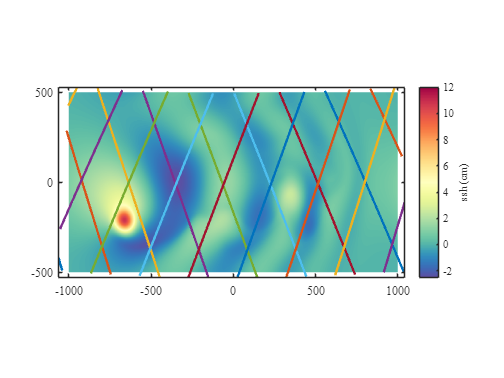


filename = 'BetaEddyOne.nc';
x = ncread([readdir, filename], 'x') / 1000; %km
y = ncread([readdir, filename], 'y') / 1000;
ssh = squeeze(ncread([readdir, filename], 'ssh')) * 100; %cm;% matrix order in x,y,z
totalDays = size(ssh, 3);
totalCycles = round(totalDays/9.915645);
%redefine x and y to be centered on the domain midpoint
xc = x - mean(x);
yc = y - mean(y);

%extract a subset of tracks

%first, grid x and y
[xg, yg] = ndgrid(xc, yc);

%covert these to longitude and latitude using a tangent plane
[latg, long] = xy2latlon(xg, yg, lato, lono); %spehrical geometry
%cylindrical coordinate with axis on the equator
% [latg,long] = TransverseMercatorToLatitudeLongitude(xg,yg,lon0=lono);
% % Normalize longitude to [-180, 180] range
% long = mod(long + 180, 360) - 180;
% latg = mod(latg + 180, 360) - 180;

%create a region enclosing minima and maxima lon and lat
region = [min(long(:)), max(long(:)), min(latg(:)), max(latg(:))];

%extract latitude and longitude for this region; t is for track
[latt, lont, timet] = trackextract(lat, lon, time, region);

%define a start date for the simulation
%timeo=datenum(1992,9,25)+(0:totalDays-1)';
timeo = datenum(2000, 1, 1) + (0:totalDays - 1)' + 90; %Initial time is also a free parameter
a = find(squeeze(min(timet, [], [1, 2])) > timeo(1), 1, 'first');
b = find(squeeze(max(timet, [], [1, 2])) < timeo(end), 1, 'last');
timet = timet(:, :, a:b);
lont = deg180(lont-lono) + lono; %avoids unwrapping issues

%finally, convert these latitudes and longitudes back to x and y
[xt, yt] = latlon2xy(latt, lont, lato, lono);

figure, jpcolor(xc, yc, ssh(:, :, end)'), hold on
plot(xt, yt, linewidth = 2), axis tight, latratio(lato),
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'ssh (cm)';
clim([-2.5, 12])

## Eddy-centered x,y track matrix

load('center_SSHMax.mat', 'center_xy')

%% 90 percent sshmax center
% [center_xy, ~]=findSSHMaxContour(x,y,ssh);

%% zeta-zero contour centroid
% [center_xy, core_xy]=findCenterZeroZeta(x,y,zeta2D,ssh2D);

## Interpolate ssht per day from the model ssh

%timeo is the model time assuming a certain start day.  timet is the alongtrack altimeter time.

xtMat = repmat(xt, [1, 1, size(timet, 3)]);
ytMat = repmat(yt, [1, 1, size(timet, 3)]);

[xMat, yMat, tMat] = ndgrid(xc, yc, timeo);
ssht = interpn(xMat, yMat, tMat, ssh, xtMat, ytMat, timet, 'linear', 0);

%find center position at exact time of each altimeter measurement
xo = interp1(timeo, center_xy(:, 1), timet) - mean(x);
yo = interp1(timeo, center_xy(:, 2), timet) - mean(y);

xEt = xt - xo;
yEt = yt - yo;

## 2D statistics

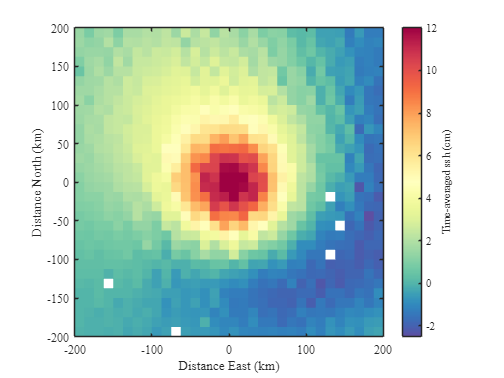


% 2D statistisc on defined bins
[mz, xmid, ymid, numz, stdz] = twodstats(xEt, yEt, ssht, -250:12.5:250, -250:12.5:250);

% mean ssh 2D
figure;
jpcolor(xmid, ymid, mz)
% jpcolor(xEbin, yEbin, AvgsshAccumBin)
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Time-averaged ssh (cm)';
xlim([-200, 200]), ylim([-200, 200]);
clim([-2.5, 12])

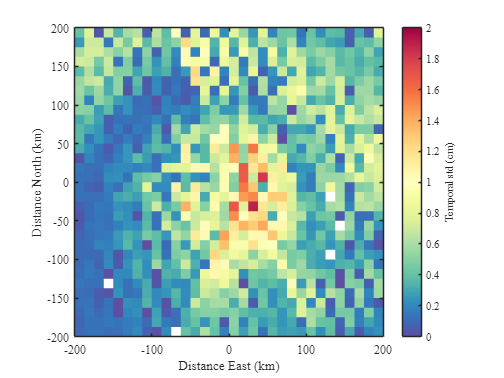

% plot 2D temporal std
figure;
jpcolor(xmid, ymid, stdz);
% jpcolor(xEbin, yEbin, stdTempD);
shading flat
% hold on
% contour(xE,yE,stdTemp2D,[0:0.1:2],'k')
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Temporal std (cm)';
xlim([-200, 200]), ylim([-200, 200]); clim([0, 2])

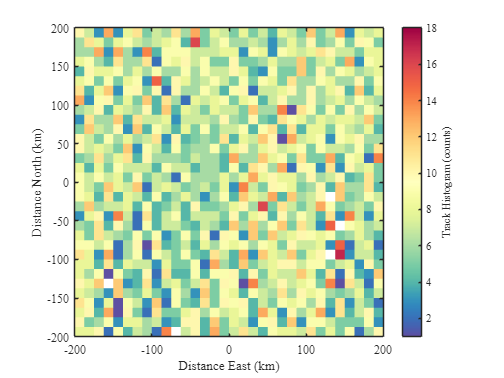

% 2D track counts histogram
figure;
numz(numz == 0) = nan;
jpcolor(xmid, ymid, numz) %
clim(round([min(numz(:)), max(numz(:))]))
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Track Histogram (counts)';
xlim([-200, 200]), ylim([-200, 200]);

## Radial statistics from tracks directly

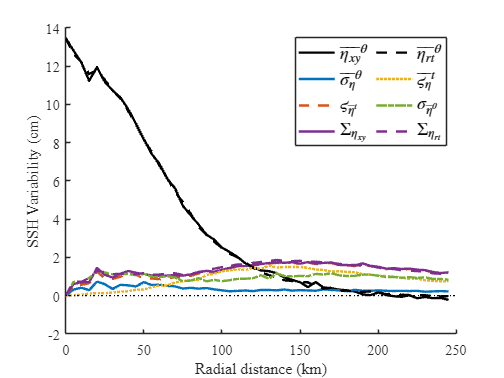

tbin = [min(timet, [], "all") - .5:1:max(timet, [], "all") + 0.5]'; %tbin for radialStatisticsFromScatter has to be per days for 'azimuthal'
rbin = [-5 / 2:5:250]';
% Compute statistics
[mzxy, rmid, numz, stdAziAvgTemp, AvgAziStdTemp] = radialStatisticsFromScatter(xEt, yEt, timet, ssht, rbin, tbin, firstAverage = 'temporal');
[mzrt, rmid, numz, stdTempAvgAzi, AvgTempStdAzi] = radialStatisticsFromScatter(xEt, yEt, timet, ssht, rbin, tbin, firstAverage = 'azimuthal');
% Std Total
stdTotalxy = sqrt(stdAziAvgTemp.^2+AvgAziStdTemp.^2);
stdTotalrt = sqrt(stdTempAvgAzi.^2+AvgTempStdAzi.^2);

%plot profile
%2k : linewidth 2, k black.
%captial A-Z in rainbow order
%T:blue, U:orange, V:yellow, X:green,W:purple
figure; hold on
h = plot(rmid, [mzxy, AvgAziStdTemp, stdAziAvgTemp, stdTotalxy, mzrt, AvgTempStdAzi, stdTempAvgAzi, stdTotalrt]);
linestyle 2k 2T 2U-- 2W 2k-- 2V: 2X-. 2W--
hlines(0, 'k:')

xlabel('Radial distance (km)', 'FontName', 'times')
ylabel('SSH Variability (cm)', 'FontName', 'times')
set(gca, 'fontname', 'times')
lg = legend(h, '$\overline{\eta_{xy}}^\theta$', '$\overline{\sigma_\eta}^\theta$', '$\varsigma_{\overline{\eta}^t}$', '$\Sigma_{\eta_{xy}}$', '$\overline{\eta_{rt}}^\theta$', '$\overline{\varsigma_\eta}^t$', '$\sigma_{\overline{\eta}^\theta}$', '$\Sigma_{\eta_{rt}}$');
set(lg, 'interpreter', 'latex', 'fontsize', 15, 'orientation', 'vertical', 'NumColumns', 2)
set(gca, 'fontsize', 12)
xlim([0, 250]); ylim([-2, 14])

## r vs t directly from track

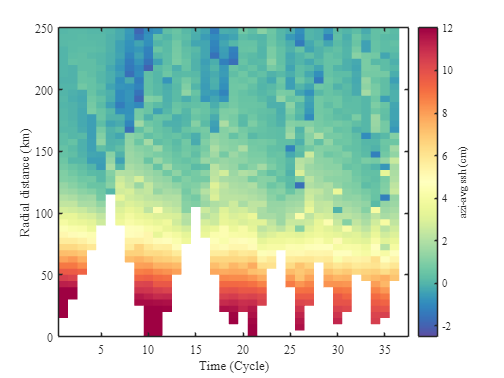

%let's make a cycle number array the same size as xEt
tmat = repmat(permute((1:size(timet, 3))', [3, 2, 1]), [size(xEt, 1), size(yEt, 2)]);
[mz_rt, rmid, tmid, numz_rt, stdz_rt] = twodstats(sqrt(xEt.^2+yEt.^2), tmat, ssht, (0:5:250), 0.5:37.5);

figure;
hold on;
jpcolor(tmid, rmid, mz_rt'), ylim([0, 250]) %mz_rt'./vmean(mz_rt,2)'
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'azi-avg ssh (cm)';
set(gca, 'fontname', 'times')
clim([-2.5, 12])

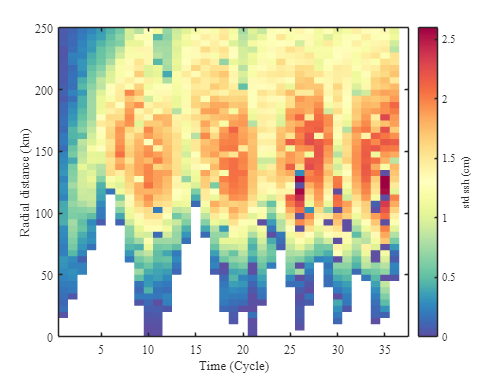

figure;
hold on;
jpcolor(tmid, rmid, stdz_rt'), ylim([0, 250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'std ssh (cm)';
set(gca, 'fontname', 'times')

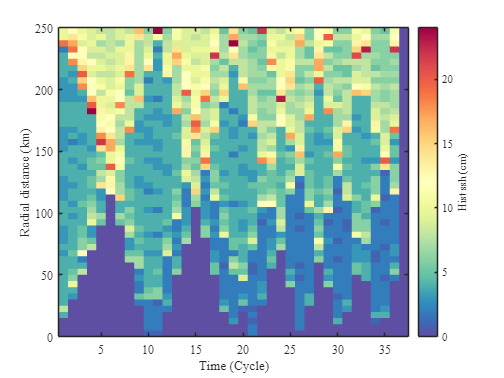

% clim([0,2.5])
figure;
hold on;
jpcolor(tmid, rmid, numz_rt'), ylim([0, 250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Hist ssh (cm)';
set(gca, 'fontname', 'times')

## Full resolution radial statistics

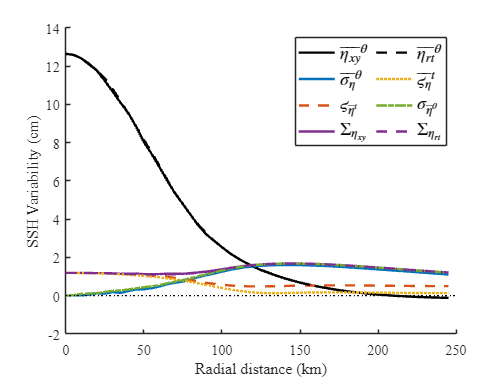

% [xMat,yMat,tMat]=ndgrid(xc,yc,timeo);
%find center position at exact time of each altimeter measurement
xo_full = repmat(permute((center_xy(:, 1) - mean(x)), [3, 2, 1]), [size(xMat, 1), size(xMat, 2)]); %matrix size to be x,y,t
yo_full = repmat(permute((center_xy(:, 2) - mean(y)), [3, 2, 1]), [size(xMat, 1), size(xMat, 2)]);

xE = xMat - xo_full;
yE = yMat - yo_full;

tbin = [min(tMat, [], "all") - .5:1:max(tMat, [], "all") + 0.5]'; %[0.5:1:totalDays+0.5]';%[1:totalDays]; %tbin for radialStatisticsFromScattered has to be per days for 'azimuthal'
rbin = [-5 / 2:5:250]';
% Compute statistics
[mzxy_full, rmid, numz, std1_full, std2_full] = radialStatisticsFromScatter(xE, yE, tMat, ssh, rbin, tbin, firstAverage = 'temporal');
[mzrt_full, rmid, numz, std3_full, std4_full] = radialStatisticsFromScatter(xE, yE, tMat, ssh, rbin, tbin, firstAverage = 'azimuthal');
% Std Total
stdTotalxy_full = sqrt(std1_full.^2+std2_full.^2);
stdTotalrt_full = sqrt(std3_full.^2+std4_full.^2);

figure; hold on
h = plot(rmid, [mzxy_full, std1_full, std2_full, stdTotalxy_full, mzrt_full, std3_full, std4_full, stdTotalrt_full]);
linestyle 2k 2T 2U-- 2W 2k-- 2V: 2X-. 2W--
hlines(0, 'k:')

xlabel('Radial distance (km)', 'FontName', 'times')
ylabel('SSH Variability (cm)', 'FontName', 'times')
set(gca, 'fontname', 'times')
lg = legend(h, '$\overline{\eta_{xy}}^\theta$', '$\overline{\sigma_\eta}^\theta$', '$\varsigma_{\overline{\eta}^t}$', '$\Sigma_{\eta_{xy}}$', '$\overline{\eta_{rt}}^\theta$', '$\overline{\varsigma_\eta}^t$', '$\sigma_{\overline{\eta}^\theta}$', '$\Sigma_{\eta_{rt}}$');
set(lg, 'interpreter', 'latex', 'fontsize', 15, 'orientation', 'vertical', 'NumColumns', 2)
set(gca, 'fontsize', 12)
xlim([0, 250]); ylim([-2, 14])

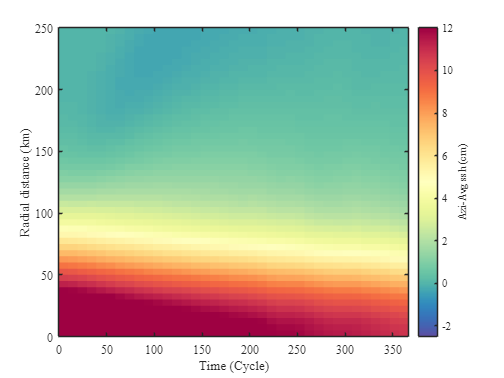


tmat_full = repmat(permute((1:size(tMat, 3))', [3, 2, 1]), [size(xMat, 1), size(xMat, 2)]);
[mz_full, rmid, tmid, numz_full, stdz_full] = twodstats(sqrt(xE.^2+yE.^2), tmat_full, ssh, (0:5:250), -0.5:9.92:367.5);

figure;
jpcolor(tmid, rmid, mz_full'), ylim([0, 250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Azi-Avg ssh (cm)';
set(gca, 'fontname', 'times')
clim([-2.5, 12])

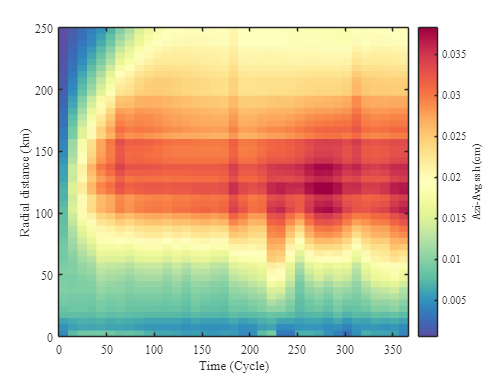

figure;
jpcolor(tmid, rmid, stdz_full'./sqrt(numz_full')), ylim([0, 250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Azi-Avg ssh (cm)';
set(gca, 'fontname', 'times')

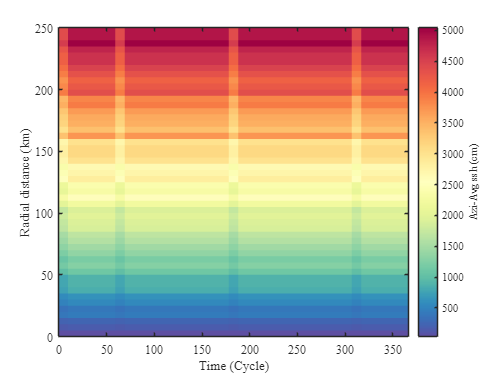

% clim([0,2.5])
figure;
hold on;
jpcolor(tmid, rmid, numz_full'), ylim([0, 250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'Azi-Avg ssh (cm)';
set(gca, 'fontname', 'times')

## Track error contribution (track, but center not shifted)

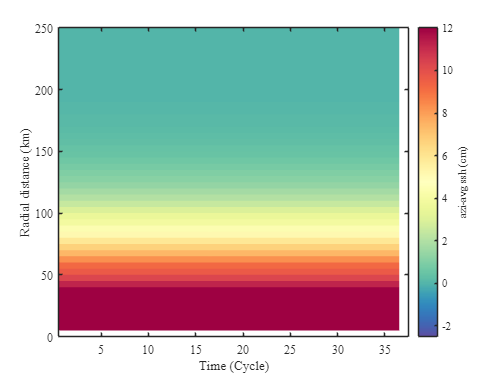

% xMat_shift = xMat + (repmat(permute(center_xy(:, 1), [3, 2, 1]), [size(xMat, 1), size(xMat, 2)]) - mean(x));
% yMat_shift = yMat + (repmat(permute(center_xy(:, 2), [3, 2, 1]), [size(xMat, 1), size(xMat, 2)]) - mean(y));

ssht_day1 = interpn(xMat, yMat, tMat, repmat(squeeze(ssh(:, :, 1)), [1, 1, size(ssh, 3)]), xtMat, ytMat, timet, 'linear', 0);
%find center position at exact time of each altimeter measurement
xEt_day1=xt-(interp1(timeo,repmat(center_xy(1,1),[size(ssh,3) 1]),timet)-mean(x));
yEt_day1=yt-(interp1(timeo,repmat(center_xy(1,2),[size(ssh,3) 1]),timet)-mean(y));
[mz_day1, rmid, tmid, numz_day1, stdz_day1] = twodstats(sqrt(xEt_day1.^2+yEt_day1.^2), tmat, ssht_day1, (0:5:250), 0.5:37.5);

figure;
hold on;
jpcolor(tmid, rmid, mz_day1'), ylim([0, 250]) %mz_rt'./vmean(mz_rt,2)'
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'azi-avg ssh (cm)';
set(gca, 'fontname', 'times')
clim([-2.5, 12])

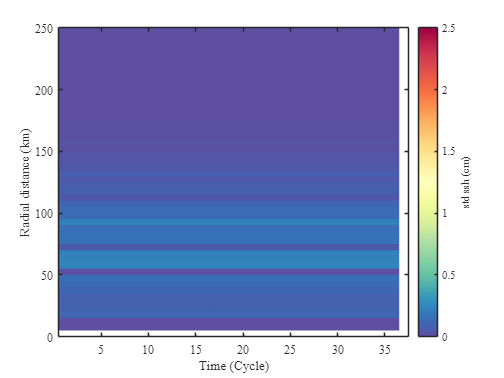

figure;
hold on;
jpcolor(tmid, rmid, stdz_day1'), ylim([0, 250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
colormap(brewermap([], '-Spectral'))
c = colorbar('EastOutside');
c.Label.String = 'std ssh (cm)';
set(gca, 'fontname', 'times')
clim([0, 2.5])

## Track cycle convergence residual

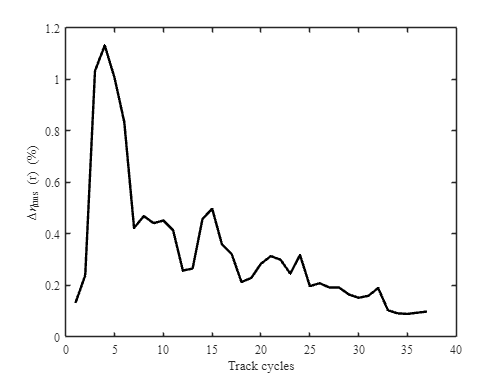

% Plot convergence rate to see how many tracks is needed
% Accumulated tracks at each cycle
cumAvg_track = cumsum(mz_rt.*numz_rt, 'omitnan') ./ cumsum(numz_rt);
cumAvg_full = cumsum(mz_full.*numz_full, 'omitnan') ./ cumsum(numz_full);
dmz = rms((cumAvg_track - cumAvg_full)./repmat(cumAvg_full(end, :), [size(cumAvg_full, 1), 1]), 2, 'omitmissing');
figure(7)
plot(1:size(mz_full, 1), dmz/rms(cumAvg_full(end, :)), 'LineWidth', 2, 'Color', 'k');
xlabel('Track cycles', 'FontName', 'times')
ylabel('\Delta\eta_{rms} (r) (%)', 'FontName', 'times')
set(gca, 'fontname', 'times')